# `EYE DIAGRAMS AND EQUALIZATION`

`EN3053 : Digital Communication-I`

`Lab Assignment: S.Sanjith-190562G`

## `Analysing the Effect of Pulse Shaping Filter`

#### `Impulse Train Representing BPSK Symbols`

Let's generate a random sequence of $L=1000$

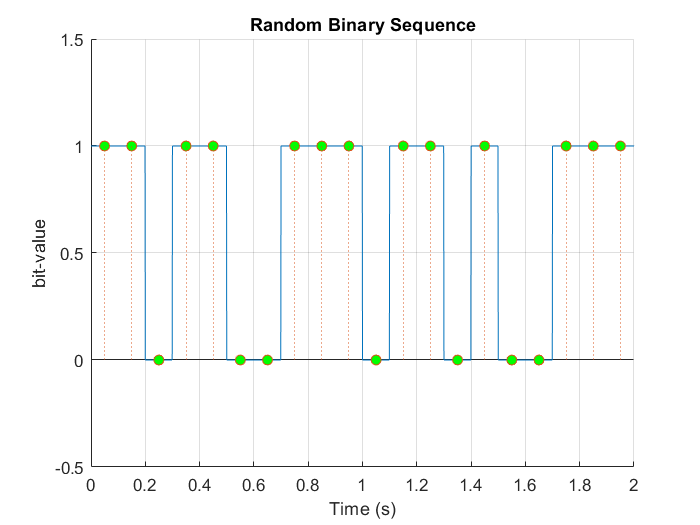

clear ; close all;
L  = 1000;
fs = 10;            % Sampling Frequency
Tb = 1/fs;
t = 0:Tb:(L-1)*Tb;
dt = 0.001;
t_ = 0:dt:L/fs-dt;   % Time Vector

% Creating Random Binary Sequence
data = randi([0 1], 1,L);
data_ = zeros(1,length(t_));
for j = 0:L-1
    data_(round(j*Tb/dt) + 1:round((j+1)*Tb/dt)) = data(j+1);
end


figure
hold on;
plot(t_,data_)
stem(t+Tb/2,data,'LineStyle',":",'MarkerFaceColor','green');
grid("on")
title("Random Binary Sequence")
ylabel("bit-value")
xlabel("Time (s)")
ylim([-0.5 1.5]);
xlim([0 2]);

Map the sequence with BPSK symbols using the following rule,

$a_k = \begin{cases} 1&b_k=1\\-1&b_k=0\end{cases}$         where $a_k$ is the amplitude of the $k^{th}$ symbol and $b_k$ is the $k^{th}$ bit.

Then an impulse train was generated which represents the BPSK symbols and given by the following equation.


$$x(t) = \sum_{k=0}^{L-1}a_k\cdot\delta(t-kT_b)$$


where the bit duration $T_b$ = 0.1s. The impulse train representing the BPSK symbols for a duration of 2s are as follows,

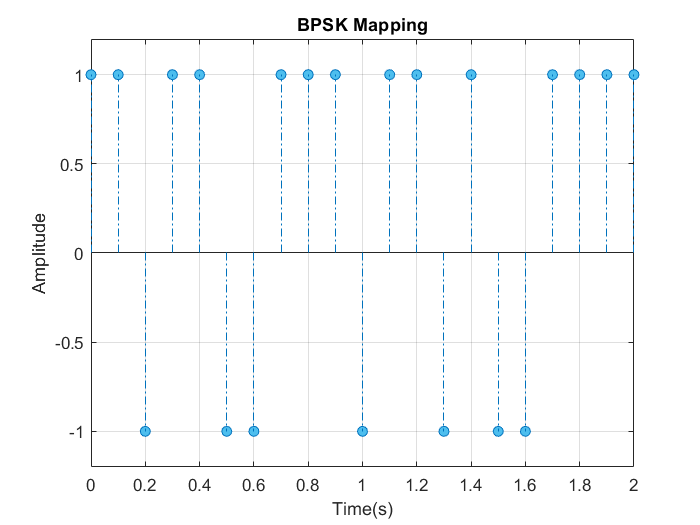

% Map the Sequence Using BPSK
x = 2*data-1;

x_ = zeros(1,length(t_));
for j = 0:L-1
    x_(round(j*Tb/dt)+1) = x(j+1);
end


figure;
stem(t,x,'LineStyle',"-.",'MarkerFaceColor','#4DBEEE');
grid("on")
title("BPSK Mapping")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([-1.2 1.2]);
xlim([0 2]);

#### Transmitted Signal

Finally the transmitted signal was created by convolving BPSK pulses with pulse shaping filters which utilize three different pulses

- Sinc Pulse

- Raised Cosine with $\alpha$ = 0.5

- Raised Cosine Pulse with $\alpha$ = 1

where $\alpha$ - roll-off factor

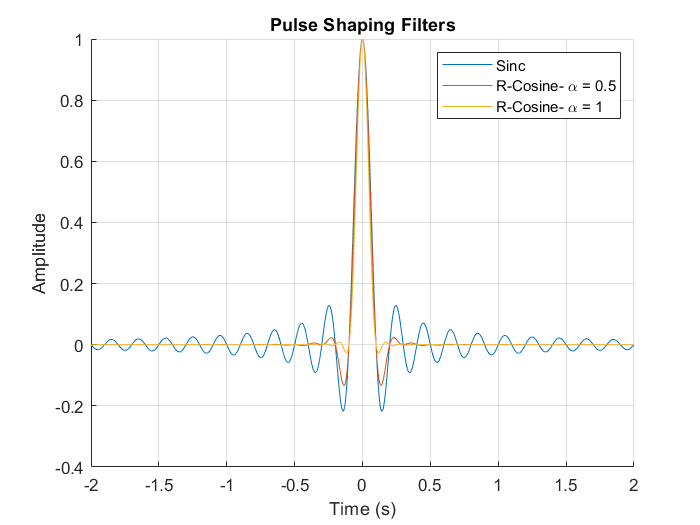

alpha_1 = 0.5;
alpha_2 = 1;
ts = -L*Tb :dt: L*Tb;

Tx_sinc = sinc(fs*ts);
Tx_rcos1 = rcos(alpha_1,fs,ts);
Tx_rcos2 = rcos(alpha_2,fs,ts);

figure;
hold on;
plot(ts,Tx_sinc);
plot(ts,Tx_rcos1);
plot(ts,Tx_rcos2);
title("Pulse Shaping Filters");
xlabel("Time (s)");
ylabel("Amplitude");
grid on;
legend(["Sinc","R-Cosine- \alpha = 0.5","R-Cosine- \alpha = 1"])
xlim([-2,2])

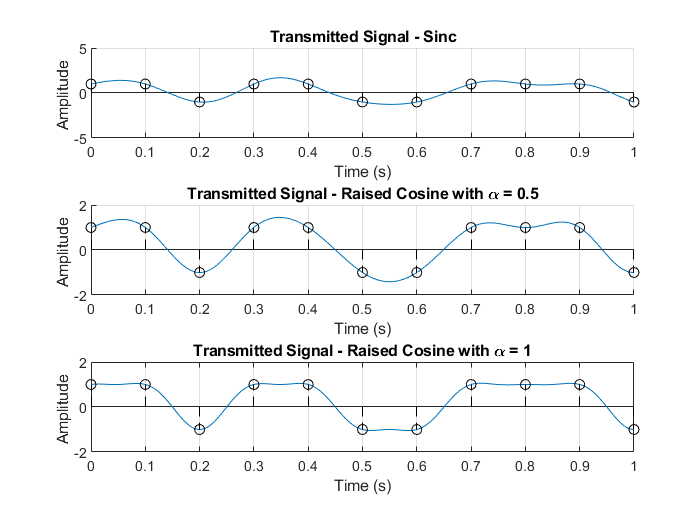

Tx_stream_sinc = conv(x_,Tx_sinc,"same");
Tx_stream_rcos1 = conv(x_,Tx_rcos1,"same");
Tx_stream_rcos2 = conv(x_,Tx_rcos2,"same");

figure
subplot(3,1,1);
hold on
plot (t_, Tx_stream_sinc );
stem (t ,x ,'k','LineStyle','--');
xlabel ('Time (s)')
ylabel ('Amplitude ')
title ('Transmitted Signal - Sinc')
xlim ([0 1])
ylim([-5 5])
grid on

subplot(3,1,2);
hold on
plot (t_, Tx_stream_rcos1 );
stem (t ,x ,'k','LineStyle','--');
xlabel ('Time (s)')
ylabel ('Amplitude ')
title ('Transmitted Signal - Raised Cosine with \alpha = 0.5')
xlim ([0 1])
ylim([-2 2])
grid on

subplot(3,1,3);
plot (t_, Tx_stream_rcos2 );
hold on
stem (t ,x ,'k','LineStyle','--');
xlabel ('Time (s)')
ylabel ('Amplitude ')
title ('Transmitted Signal - Raised Cosine with \alpha = 1')
xlim ([0 1])
ylim([-2 2])
grid on

#### Eye-Diagrams of Transmitted Signal

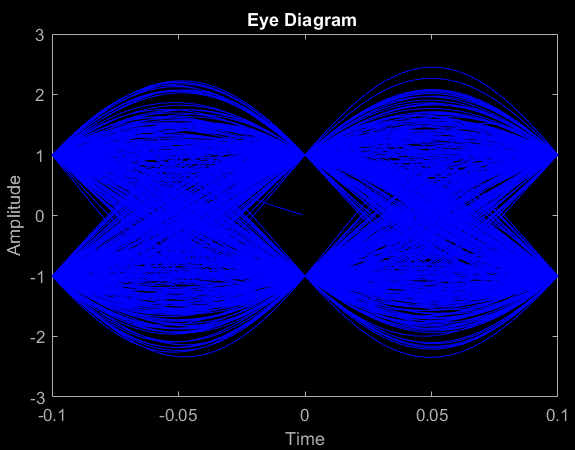

eyediagram(Tx_stream_sinc,2*Tb/dt,2/fs,0,'b-')

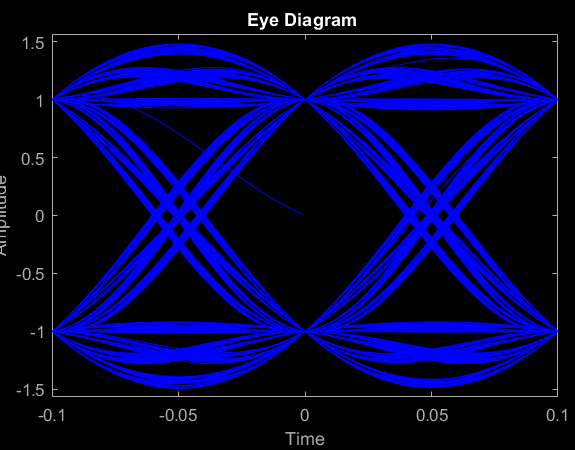

eyediagram(Tx_stream_rcos1,2*Tb/dt,2/fs,0,'b-')

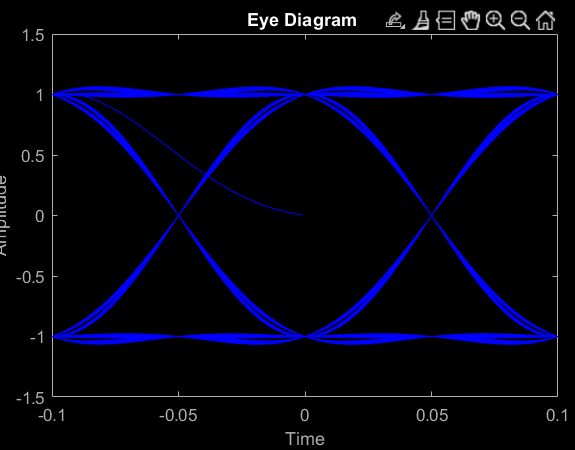

eyediagram(Tx_stream_rcos2,2*Tb/dt,2/fs,0,'b-')

## `Analyzing the Effect of AWGN Noise`

#### `Received Signal`

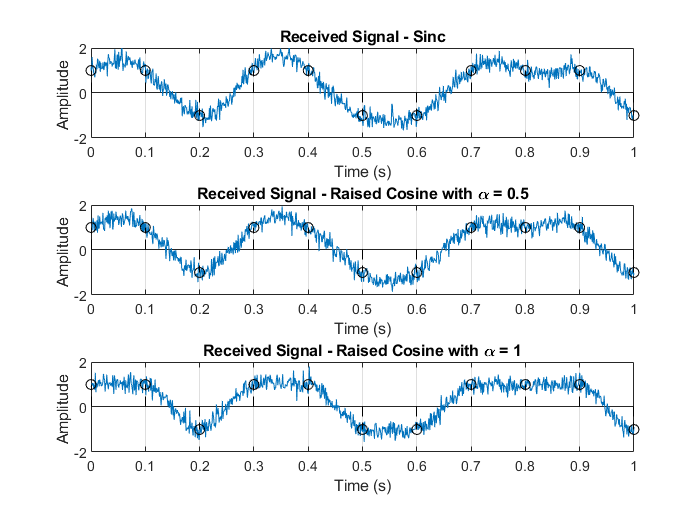

% Adding Channel Noise
Rx_stream_sinc = awgn(Tx_stream_sinc,13.14);
Rx_stream_rcos1 = awgn(Tx_stream_rcos1,13.14);
Rx_stream_rcos2 = awgn(Tx_stream_rcos2,13.14);

figure
subplot(3,1,1);
plot (t_, Rx_stream_sinc );
hold on
stem (t ,x ,'k','LineStyle','--');
xlabel ('Time (s)')
ylabel ('Amplitude ')
title ('Received Signal - Sinc')
xlim ([0 1])
ylim([-2 2])
grid on

subplot(3,1,2);
plot (t_, Rx_stream_rcos1 );
hold on
stem (t ,x ,'k','LineStyle','--');
xlabel ('Time (s)')
ylabel ('Amplitude ')
title ('Received Signal - Raised Cosine with \alpha = 0.5')
xlim ([0 1])
ylim([-2 2])
grid on

subplot(3,1,3);
plot (t_, Rx_stream_rcos2 );
hold on
stem (t ,x ,'k','LineStyle','--');
xlabel ('Time (s)')
ylabel ('Amplitude ')
title ('Received Signal - Raised Cosine with \alpha = 1')
xlim ([0 1])
ylim([-2 2])
grid on

#### Eye-Diagrams of Received Signal

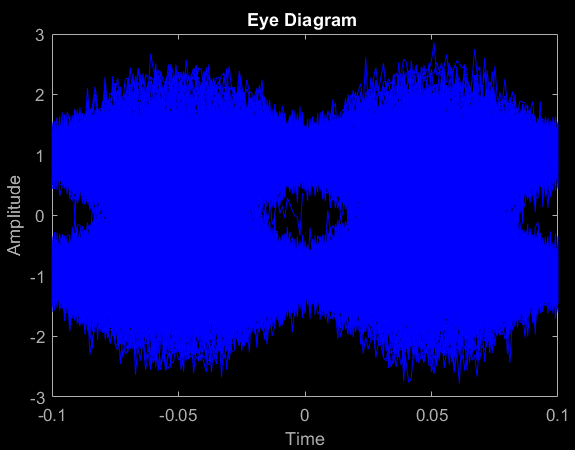

eyediagram(Rx_stream_sinc,2*Tb/dt,2/fs,0,'b-')

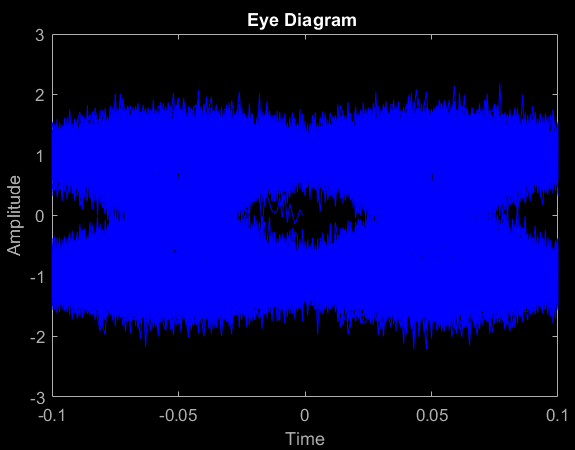

eyediagram(Rx_stream_rcos1,2*Tb/dt,2/fs,0,'b-')

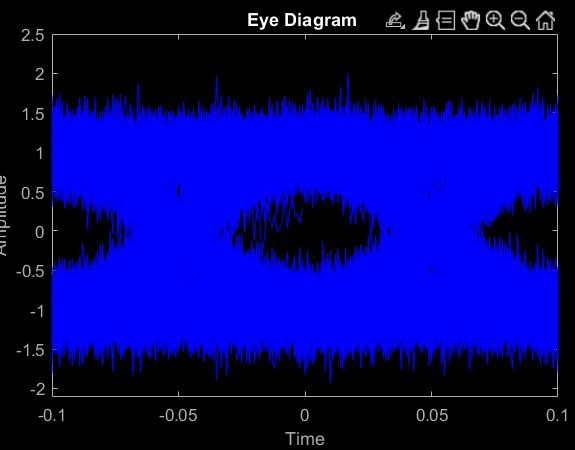

eyediagram(Rx_stream_rcos2,2*Tb/dt,2/fs,0,'b-')

## `Delay Compensation with Zero-Forcing Filter`

`Lets generate a binary sequence similar to task 1`

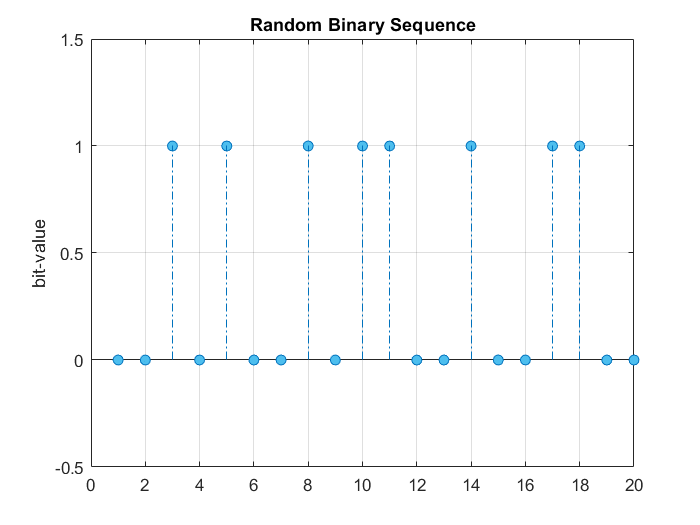

clear ; close all;
L  = 10000;
fs = 10;            % Sampling Frequency
Tb = 1/fs;
t =0:Tb:(L-1)*Tb;

% CREATING RANDOM BINARY SEQUENCE
data = randi([0 1], 1,L);

figure
stem(data,'LineStyle',"-.",'MarkerFaceColor','#4DBEEE');
grid("on")
title("Random Binary Sequence")
ylabel("bit-value")
ylim([-0.5 1.5]);
xlim([0 20]);

The mapping is done using BPSK scheme

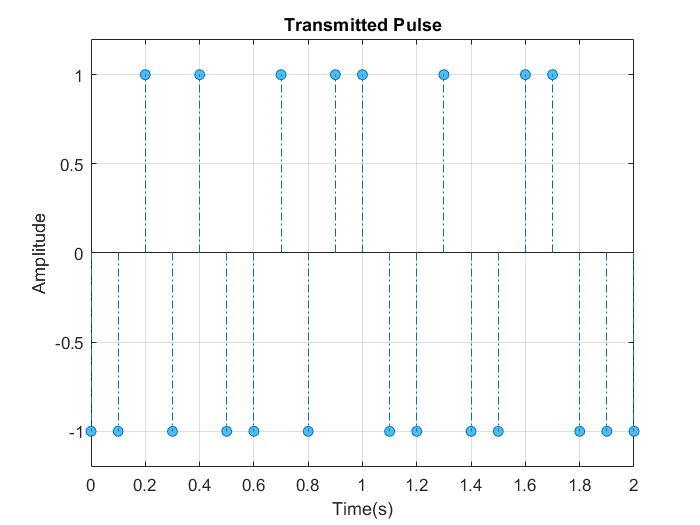

% Map the Sequence Using BPSK
x = 2*data-1;

figure;
stem(t,x,'LineStyle',"-.",'MarkerFaceColor','#4DBEEE');
grid("on")
title("Transmitted Pulse")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([-1.2 1.2]);
xlim([0 2]);

#### Delay Distortion


$$h = [0.3,0.9,0.4]$$


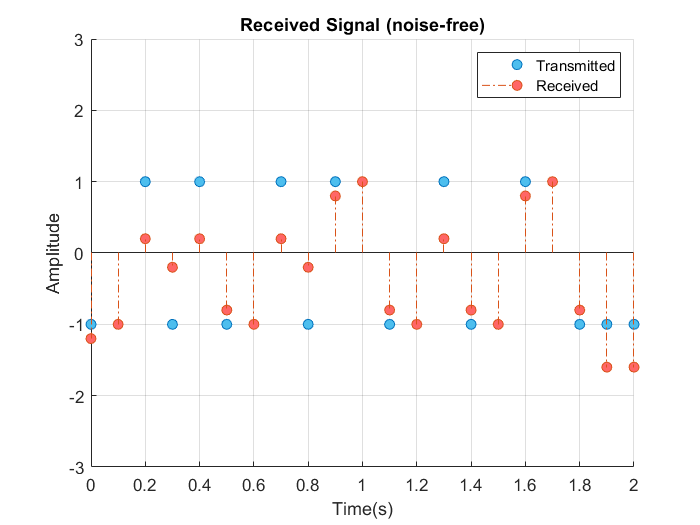

% Channel-Delay Characteristics
h = [0.3 0.9 0.4];
l_ = floor(length(h)/2);                % Number of samples to disgard
y = conv(x,h,"same");


figure
hold on;
stem(t,x,'MarkerFaceColor','#4DBEEE','LineStyle',"none");
stem(t,y,'filled',"LineStyle","-.",'MarkerFaceColor','#FF6666');
grid("on")
title("Received Signal (noise-free)")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([-3 3]);
xlim([0 2]);
legend(["Transmitted","Received"])

#### Noise Distortion

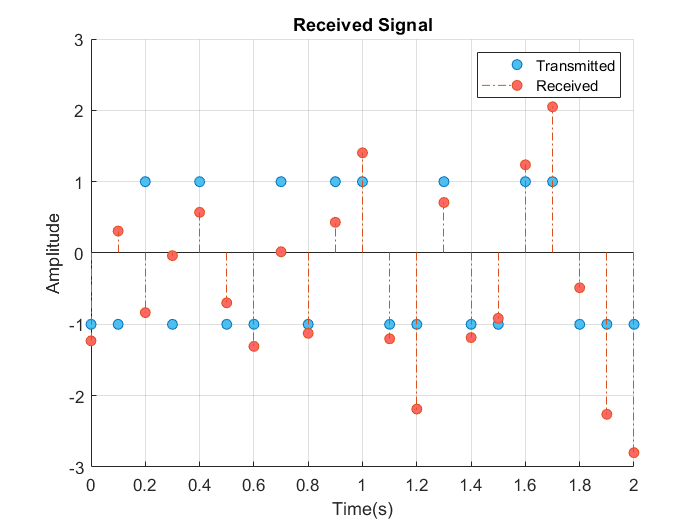

% Channel Noise
noisy_y = awgn(y,3.14);

figure
hold on;
stem(t,x,'MarkerFaceColor','#4DBEEE','LineStyle',"none");
stem(t,noisy_y,'filled',"LineStyle","-.",'MarkerFaceColor','#FF6666');
grid("on")
title("Received Signal")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([-3 3]);
xlim([0 2]);
legend(["Transmitted","Received"])

#### ZF-Equalization

At the receiver end, let's design a Zero-Forcing Equalization filter inorder to compensate the distortions from channel.

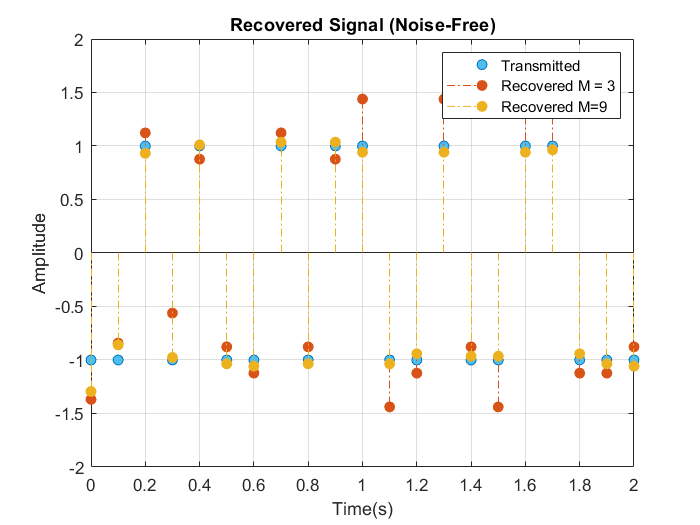

% M-Tap Equalization Filter
figure
stem(t,x,'MarkerFaceColor','#4DBEEE','LineStyle',"none");
hold on;

for M = [3 9]
    he = ZF_coff(max(M,length(h)),h,L);
    recovered = conv(y,he([(end-M)/2+1:(end+M)/2]),"same");
    
    stem(t,recovered,'filled',"LineStyle","-.");
end

grid("on")
title("Recovered Signal (Noise-Free)")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([-2 2]);
xlim([0 2]);
legend(["Transmitted","Recovered M = 3","Recovered M=9"])

`Equalization on Noisy Signal`

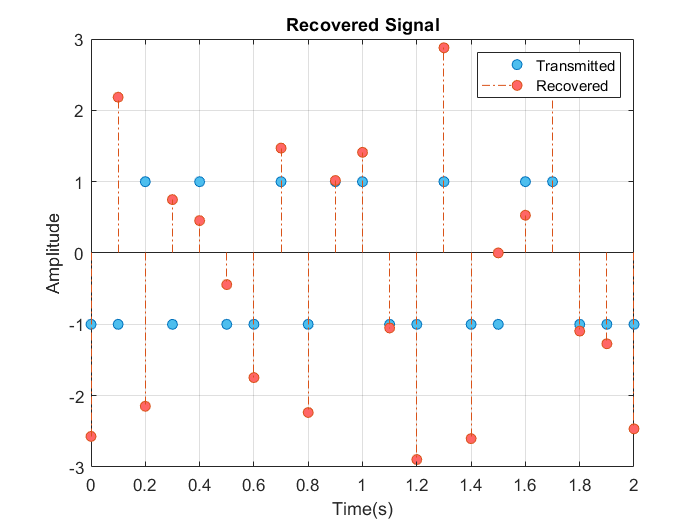

% Equalization on Noisy Signal
recovered = conv(noisy_y,he([(end-M)/2+1:(end+M)/2]),"same");


figure
stem(t,x,'MarkerFaceColor','#4DBEEE','LineStyle',"none");
hold on;
stem(t,recovered,'filled',"LineStyle","-.",'MarkerFaceColor','#FF6666');

grid("on")
title("Recovered Signal")
ylabel("Amplitude")
xlabel("Time(s)")
ylim([-3 3]);
xlim([0 2]);
legend(["Transmitted","Recovered"])

`Demodulation`

Simple decisition boundry y=0 is used to seperate between symbols.

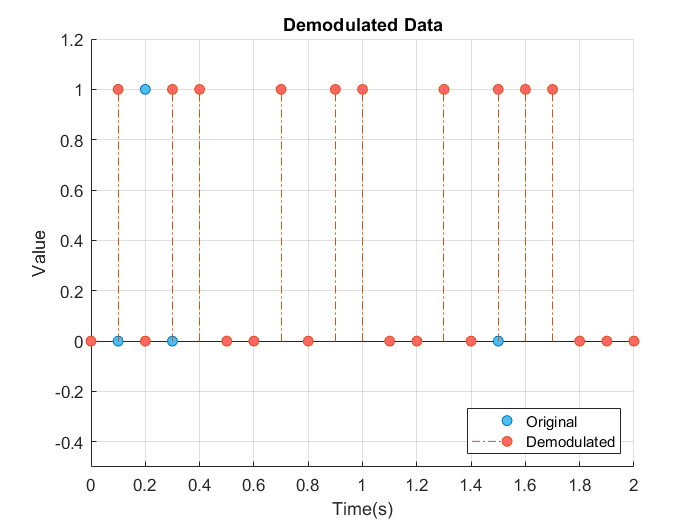

% De-Modulation
d_mod = recovered > 0;

figure
hold on;
stem(t,data,'MarkerFaceColor','#4DBEEE','LineStyle',"none");
stem(t,d_mod,'filled',"LineStyle","-.",'MarkerFaceColor','#FF6666');
grid("on")
title("Demodulated Data")
ylabel("Value")
xlabel("Time(s)")
ylim([-0.5 1.2]);
xlim([0 2]);
legend(["Original","Demodulated"],'Location','southeast')

% BER calculation
n_errors = biterr(data,d_mod);
p_error = n_errors/L

p_error = 0.2482

#### Error Comparisions

`Variation of BER with M`

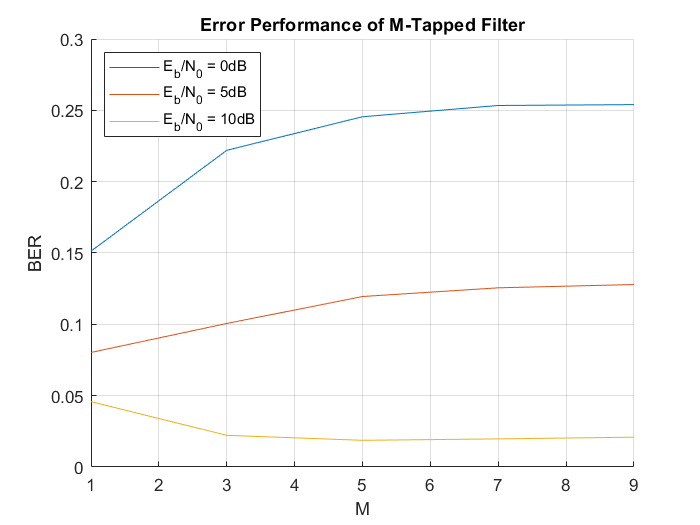

figure;
hold on;
for snr = [0 5 10]+3.14
    noisy_y = awgn(y,snr);
    p_error = [];
    for M = 1:2:9
        he = ZF_coff(max(M,length(h)),h,L);
        recovered = conv(noisy_y,he([(end-M)/2+1:(end+M)/2]),"same");
        d_mod = recovered > 0;
        n_errors = biterr(data,d_mod);
        p_error = [p_error n_errors/L];
    end
    plot(1:2:9,p_error);
end
grid on;
title("Error Performance of M-Tapped Filter");
ylabel("BER")
xlabel("M")
legend(["E_b/N_0 = 0dB","E_b/N_0 = 5dB","E_b/N_0 = 10dB"],"location",'northwest')

`Variation of BER with `$\frac{E_b}{N_0}$

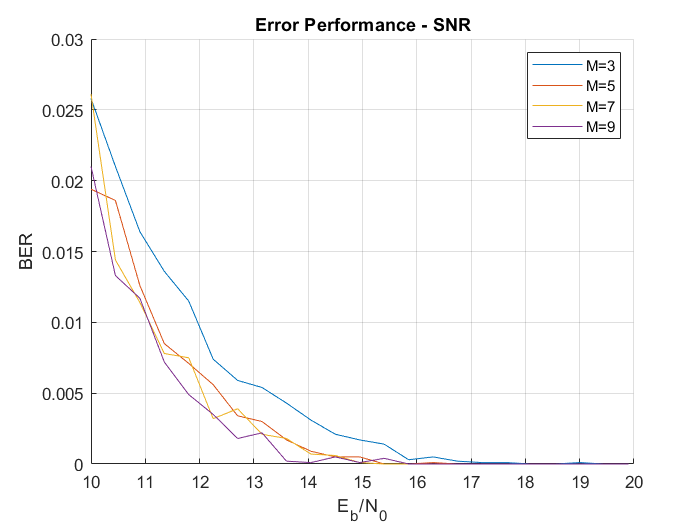

Eb_N0 = 10:0.45:20;

figure;
hold on;
for M = 3:2:9
    p_error = [];
    for snr = Eb_N0 + 3.14
        noisy_y = awgn(y,snr);
        he = ZF_coff(max(M,length(h)),h,L);
        recovered = conv(noisy_y,he([(end-M)/2+1:(end+M)/2]),"same");
        d_mod = recovered > 0;
        n_errors = biterr(data,d_mod);
        p_error = [p_error n_errors/L];
    end
    plot(Eb_N0,p_error)
end

grid on;
title("Error Performance - SNR");
xlabel("{E_b}/{N_0}");
ylabel("BER");
legend(["M=3","M=5","M=7","M=9"]);

## APPENDIX

**Raised Cosine Function **

$p(t)=sinc(\pi R_bt)\cdot \frac{cos(\pi R_bt)}{1-4r^2R_b^2t^2}$ where $R_b$ - sampling rate &  r- roll-off factor

function [output] = rcos(alpha,Rb,t)
    output = cos(pi*alpha*Rb*t).*sinc(Rb*t)./(1-(2*alpha*Rb*t).^2);
end

**Cofficients of ZF-Equlizer **

It is assumed that, at the receiver end response of a delta function is predicted correctly without the effect of noise (through averaging). Lets use this knowledge to derive the cofficients of equalization filter.

function [he] = ZF_coff(M,hc,L) 
    hc = [zeros(1,(M-length(hc))/2) hc zeros(1,(M-length(hc))/2)];
    delta = zeros(1,M);
    delta(round(end/2)) = 1;
    p = conv(delta,hc);
    r = p([round(end/2):-1:1]);
    c = p([ round(end/2):end ]);
    T = toeplitz(c,r);
    coff = inv(T)*reshape(delta,[M 1]);
    he = reshape(coff,[1,M]);
end